# Test for STC path generation

## preparation

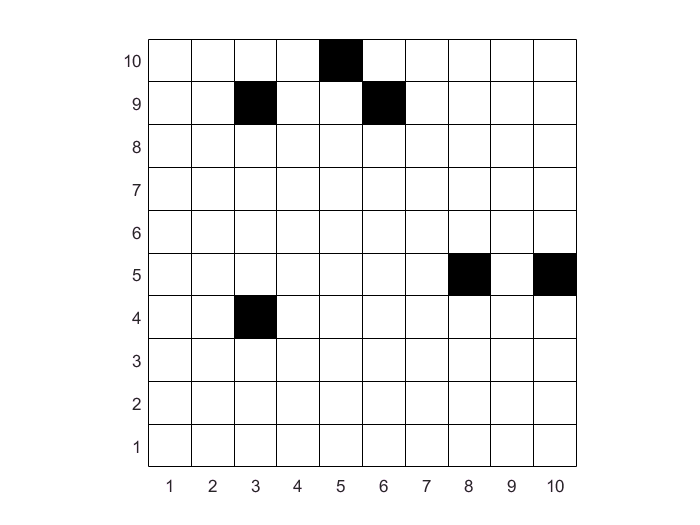

LENGTH = 20;

rng(30,'twister');
A_core = unifrnd(0,1,[LENGTH/2,LENGTH/2]);
den = 0.05;
A_core(A_core>den) = 1;% freee space
A_core(A_core<den) = 0;% obstacle

B = A_core;
B(end+1,end+1) = 0;

colormap([0 0 0;1 1 1]);  % color
pcolor(0.5:size(A_core,2)+0.5,0.5:size(A_core,1)+0.5,B); % grid color
set(gca,'XTick',1:size(A_core,2),'YTIck',1:size(A_core,1)); 
axis image xy;  % axis image is the same as axis equal except that the plot box fits tightly around the data.



kn = ones(2);
A = kron(A_core,kn);

%B = A;
%B(end+1,end+1) = 0;
%
%colormap([0 0 0;1 1 1]);  % color
%pcolor(0.5:size(A,2)+0.5,0.5:size(A,1)+0.5,B); % grid color
%set(gca,'XTick',1:size(A,2),'YTIck',1:size(A,1)); 
%axis image xy;  % axis image is the same as axis equal except that the plot box fits tightly around the data.



## Generate Spanning tree

start_p = round(unifrnd(1,LENGTH/2,[2,1]))

start_p =      9
     4


if A_core(start_p(2),start_p(1))==1
    'good'
end

ans = good

K = zeros(LENGTH/2); % Input
for j=1:LENGTH/2
    for i=1:LENGTH/2
        if A_core(j,i)==1
            K(j,i) = 1;
        end
    end
end
dir = [0 1 0 -1;1 0 -1 0];
Total_num = sum(sum(K))

Total_num = 94

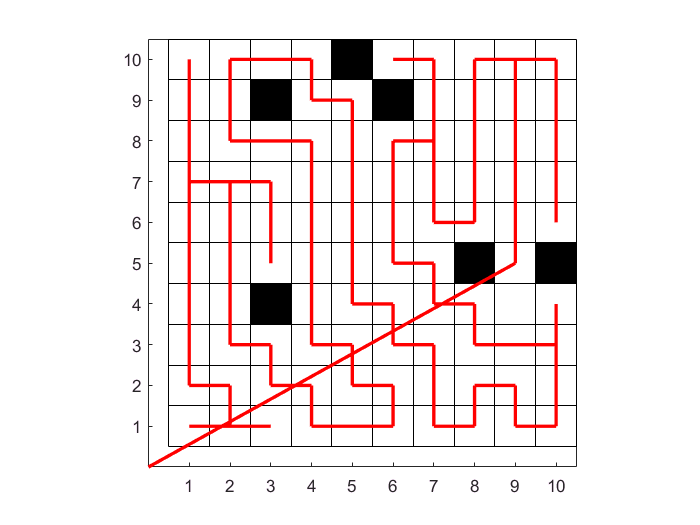

num = 2

num = 3

num = 4

num = 5

num = 6

num = 7

num = 8

num = 9

num = 10

num = 11

num = 12

num = 12

num = 12

num = 12

num = 12

num = 12

num = 13

num = 14

num = 15

num = 16

num = 17

num = 18

num = 19

num = 20

num = 21

num = 22

num = 23

num = 23

num = 23

num = 23

num = 24

num = 25

num = 26

num = 27

num = 28

num = 29

num = 30

num = 31

num = 32

num = 33

num = 34

num = 34

num = 35

num = 36

num = 37

num = 38

num = 39

num = 40

num = 41

num = 42

num = 43

num = 44

num = 45

num = 46

num = 47

num = 48

num = 49

num = 50

num = 51

num = 52

num = 53

num = 54

num = 55

num = 56

num = 57

num = 58

num = 59

num = 60

num = 61

num = 62

num = 63

num = 64

num = 65

num = 66

num = 67

num = 68

num = 69

num = 70

num = 71

num = 72

num = 73

num = 74

num = 75

num = 76

num = 77

num = 78

num = 79

num = 80

num = 81

num = 81

num = 81

num = 81

num = 82

num = 83

num = 84

num = 85

num = 85

num = 85

num = 85

num = 86

num = 87

num = 88

num = 89

num = 90

num = 91

num = 92

num = 93

num = 93

T = zeros(LENGTH/2);
num = 1;
T(start_p(2),start_p(1)) = num;
curr_p = zeros(2,1);
for d=dir
    tem_p = start_p + d;
    if tem_p(1)<=0||tem_p(1)>LENGTH/2||tem_p(2)<=0||tem_p(2)>LENGTH/2
        continue;
    end
    if K(tem_p(2),tem_p(1))==1
        line([tem_p(1),start_p(1)],[tem_p(2),start_p(2)],'Color','r','LineWidth',2)
        curr_p = tem_p;
        num = num + 1;
        T(tem_p(2),tem_p(1)) = num;
        break;
    end
end

while num~=Total_num
    %num
    % move to free space
    move = 0;
    for d=dir
        tem_p = curr_p + d;
        if tem_p(1)<=0||tem_p(1)>LENGTH/2||tem_p(2)<=0||tem_p(2)>LENGTH/2
            continue;
        end
        if K(tem_p(2),tem_p(1))==1 && T(tem_p(2),tem_p(1))==0
            line([tem_p(1),curr_p(1)],[tem_p(2),curr_p(2)],'Color','r','LineWidth',2)
            curr_p = tem_p;
            num = num + 1;
            T(tem_p(2),tem_p(1)) = num;
            move = 1;
            break;
        end
    end
    % back to an old cell
    if move==1
        continue;
    end
    for d=dir
        tem_p = curr_p + d;
        if tem_p(1)<=0||tem_p(1)>LENGTH/2||tem_p(2)<=0||tem_p(2)>LENGTH/2
            continue;
        end
        if K(tem_p(2),tem_p(1))==1 && T(tem_p(2),tem_p(1))==T(curr_p(2),curr_p(1))-1
            curr_p = tem_p;
            break;
        end
    end
end